s0_add_paths

## The history of  OTS models: 3 versions

#### OTS_v1: before the purposal of the NOA model.

After convolution, we get the contrast energy $E(x,y,\theta)$

Normalize: 

 
$$s =  \frac{1}{N} \displaystyle\sum_{x,y,\theta}\frac{E(x,y,\theta)}{w + Z(x,y,\theta) }$$


Add gain and nonlinearity to form the BOLD prediction: 


$$\hat{y} = g s ^n$$
 

#### OTS_v2: the model submitted to the preprint

Normalize: 


$$s =  \frac{1}{N} \displaystyle\sum_{x,y,\theta}\frac{E(x,y,\theta)}{1 +w Z(x,y,\theta) }$$


Add gain and nonlinearity to form the BOLD prediction: 


$$\hat{y} = g s ^n$$
 

Notice that in this period the parameter

 $w$ is bounded by $\exp(-8)\leq w \leq \exp(6$) , which is equivalent to $3.34e-4\leq w \leq 403.43$

 $g$ is bounded by $\exp(-8)\leq g \leq \exp(5.5)$) , which is equivalent to $3.34e-4\leq w \leq 244.6919$

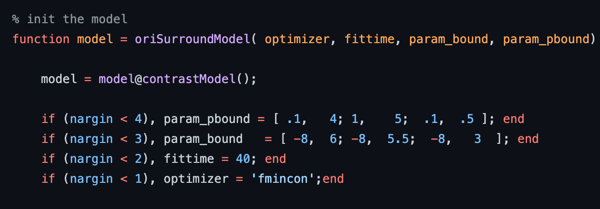

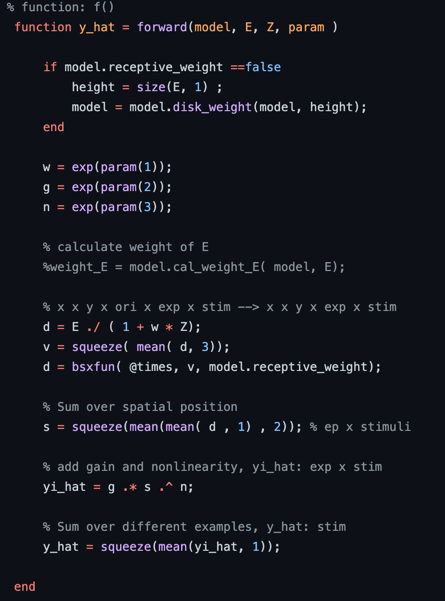

#### OTS_v3: the current model

Use the new contrast energy after the clean up. 

- Fix the filter bug.

- Remove the square root. 

- rescale the OTS filters.

## Why the OTS_v2 fails?

The most possible hypothesis is that: 

The parameter for Cross, target,

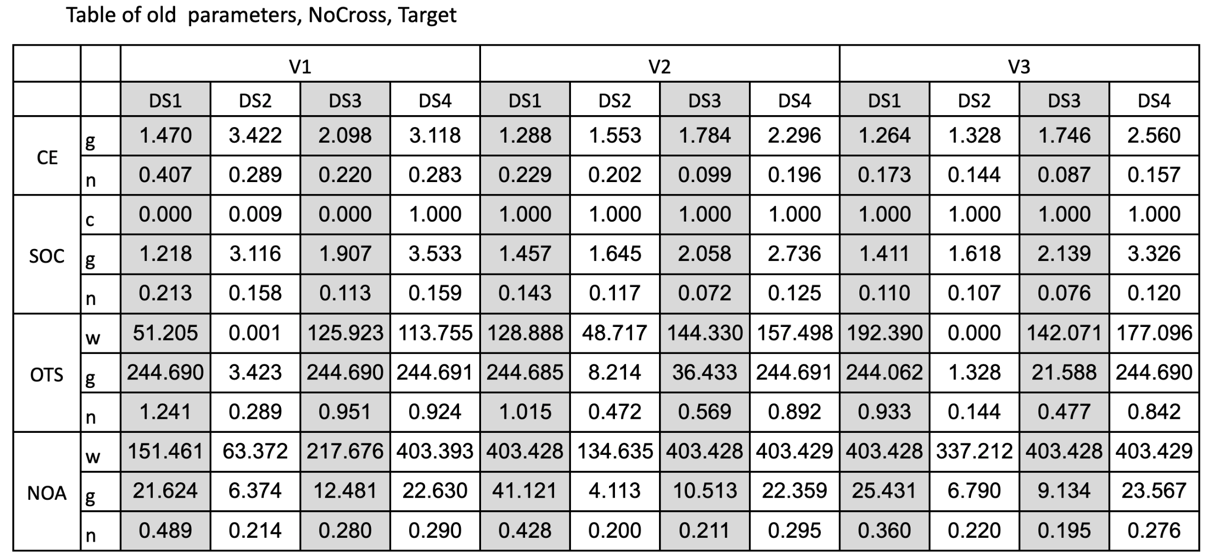

We noticed these when we submitted the draft, but we chose to make a better investigation later because the prior "the OTS model does not work". To further validate that we can fix the parameter $n$ and show the loss landscape of $g$ and $w$. 

The fit loss is:


loss_fit = 0.0781

The lowest (grid) loss within constraint:


loss_min_con = 0.0781

The lowest (grid) loss:


loss_min_global = 0.0781

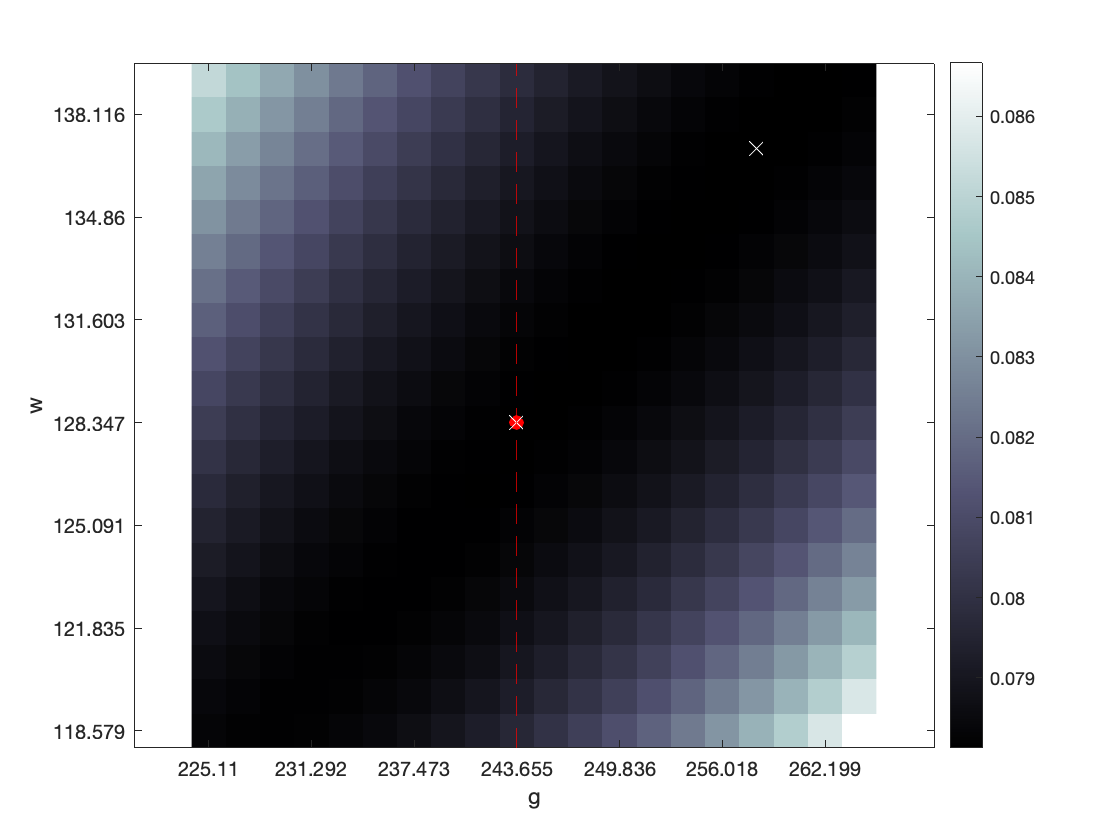

% get the old E: 
% data set=1, roi=2
% red dot is the fitted loss
% x respectively indicate the lowest loss with constraint
% and the global lowst loss
OldOTS('old_lossLand_fine'); 

Let's look at the loss landscape at a higher level with a lower resolution. The parameters g and w are correlated. A lower loss usually corresponds to a higher value of both parameters 

The question is that the lowest point is not that far from the constraint; why did the fmincon search such larger parameters (w->10e23, g-> 1e-19)? Our hypothesis is that maybe the third parameter, the exponent, is playing a role here. Next, we vary the exponent $n$.

The fit loss is:


loss_fit = 0.0781

The lowest (grid) loss within constraint:


loss_min_con = 0.0782

The lowest (grid) loss:


loss_min_global = 0.0781

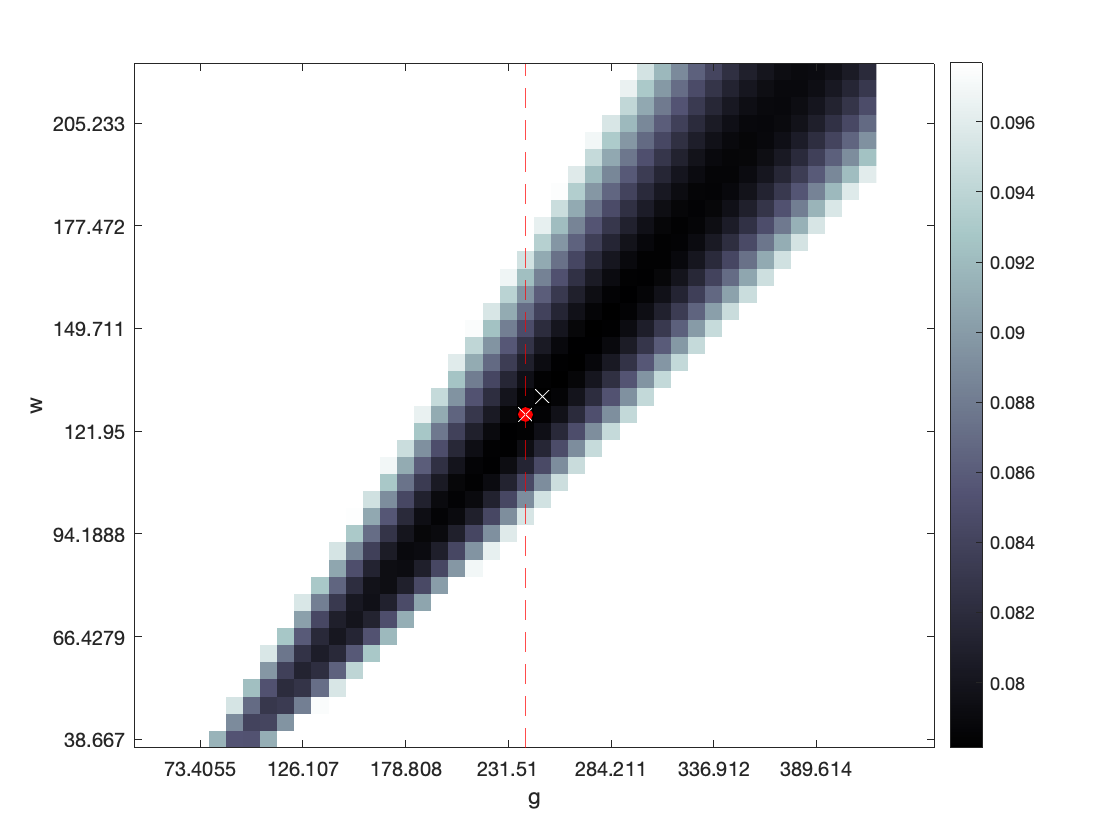

% data set=1, roi=2
% n = 1.015;
% I want to look at the losses at a higher level with a lower resolution. 
% w and g are still 
OldOTS('old_lossLand_coarse'); 

We increased $n$ from 1.015 to 1.1 and ploted the loss landscape. Compared to $n=1.105$, the larger $n$ requires a larger $g$ to reach a lower loss. This correlation may cause the searching algorithm to return extremely large values, just as we currently have. 

The fit loss is:


loss_fit = 0.1331

The lowest (grid) loss within constraint:


loss_min_con = 0.0808

The lowest (grid) loss:


loss_min_global = 0.0781

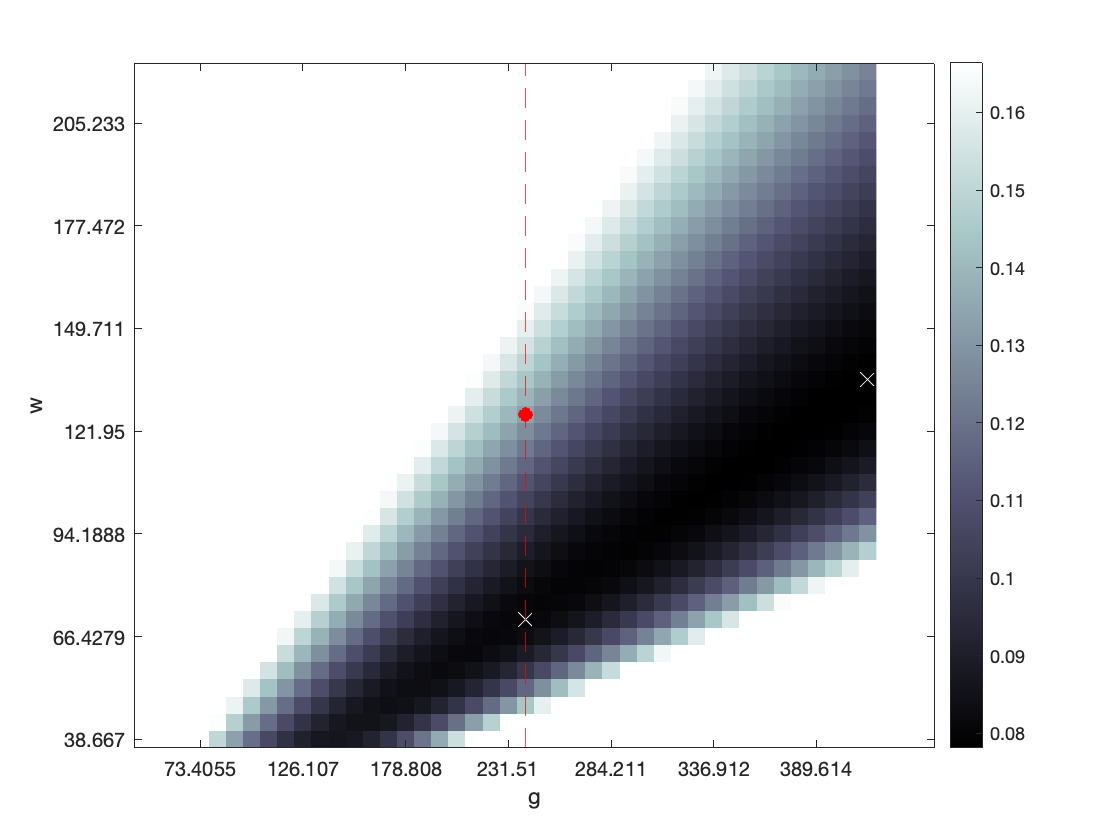

ds =1; roi=2; n_select = 1.1;
OldOTS('old_lossLand_coarse', ds, roi, n_select); 

## The loss landscape of the current OTS_v3

Many things happened after the draft submission, fixing the filters, removing the square root, etc. We want to have an intuition of the new landscape. Still, I fixed the $n=0.75$ (now $n\in(0,1)$) and varied the other two.

The lowest (grid) loss:


loss_min_global = 0.0690

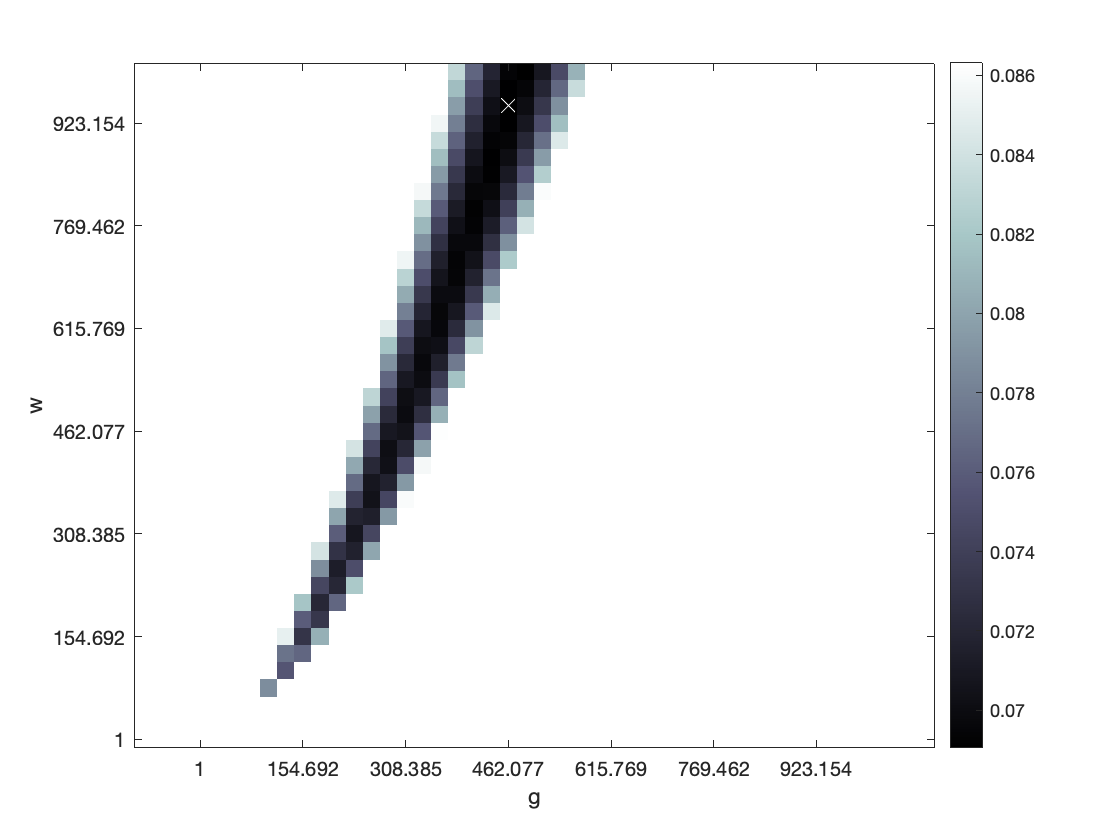

n_select = .75;
OldOTS('OTS_v3_lossLand', ds, roi, n_select); 

We then increase $n$ to 0.95. A similar conclusion we can reach is the increasing $n$ requires a larger $g$ value. 

The lowest (grid) loss:


loss_min_global = 0.0817

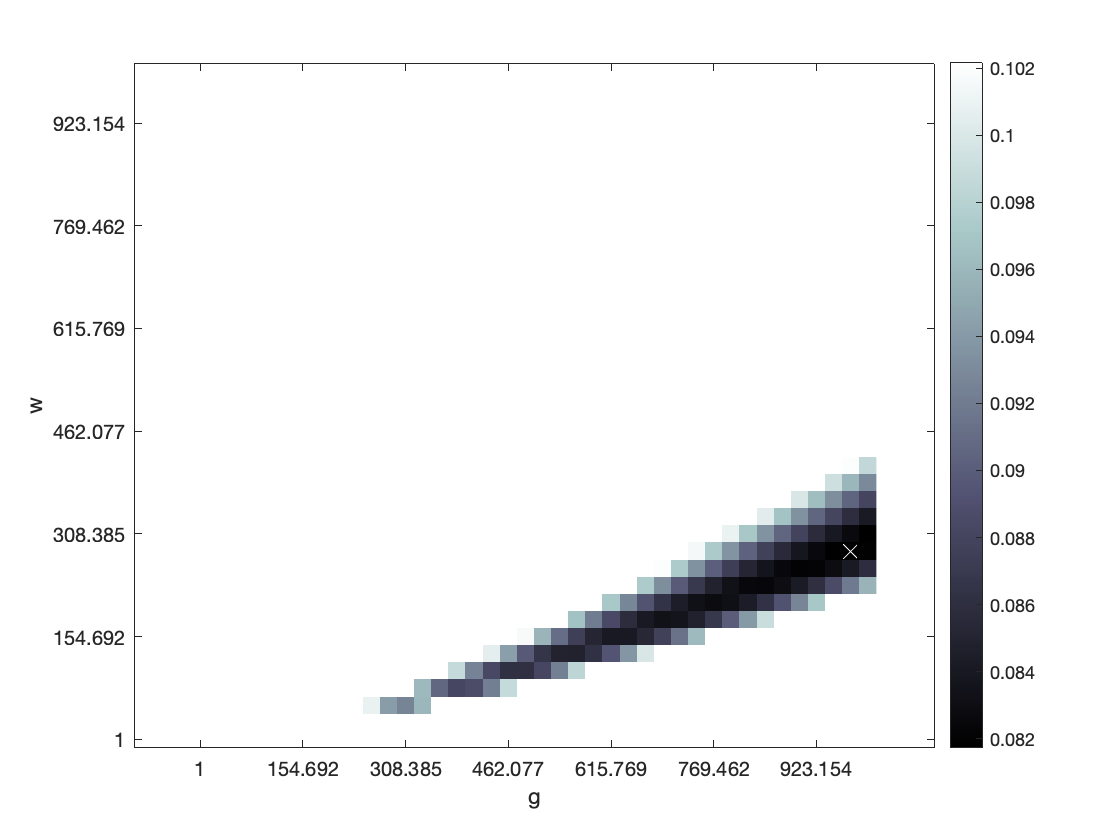

n_select = .95;
OldOTS('OTS_v3_lossLand', ds, roi, n_select); 

## Remove the redundacy in the OTS_v3.

The figures show that the parameters g and w interact with each other--increasing one parameter affects the other. We want to remove this dependency and make two parameters orthogonal. 

## 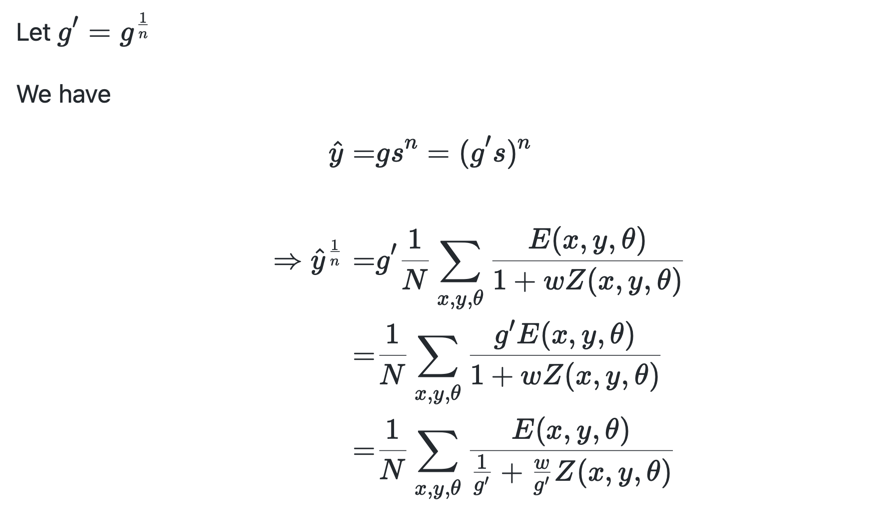

Here $\frac{1}{g'} + \frac{w}{g}Z(x,y,\theta)$ is a linear regression where $\frac{1}{g}$ is the bias and $\frac{w}{g'}$ is the slope. The problem is that the parameter $g'$ appears in both terms, resulting in that the value of slope depends on the value of bias. 

To disassociate them, we can let $\frac{1}{g'}=b$ and $\frac{w}{g}=w$. So the OTS model can be rewritten as,


$$s = \frac{1}{N}\sum_{x,y,\theta} \frac{E(x,y,\theta)}{b + wZ(x,y,\theta)}$$



$$\hat{y} = s^n$$


Let's look at the loss landscape of the new OTS model. Increase $b$ does not have a significant impact on $w$, meaning that the redudancy is largely reduced. Still, there is some correlation introduced by the exponent $n$. 

The lowest (grid) loss:


loss_min_global = 0.0593

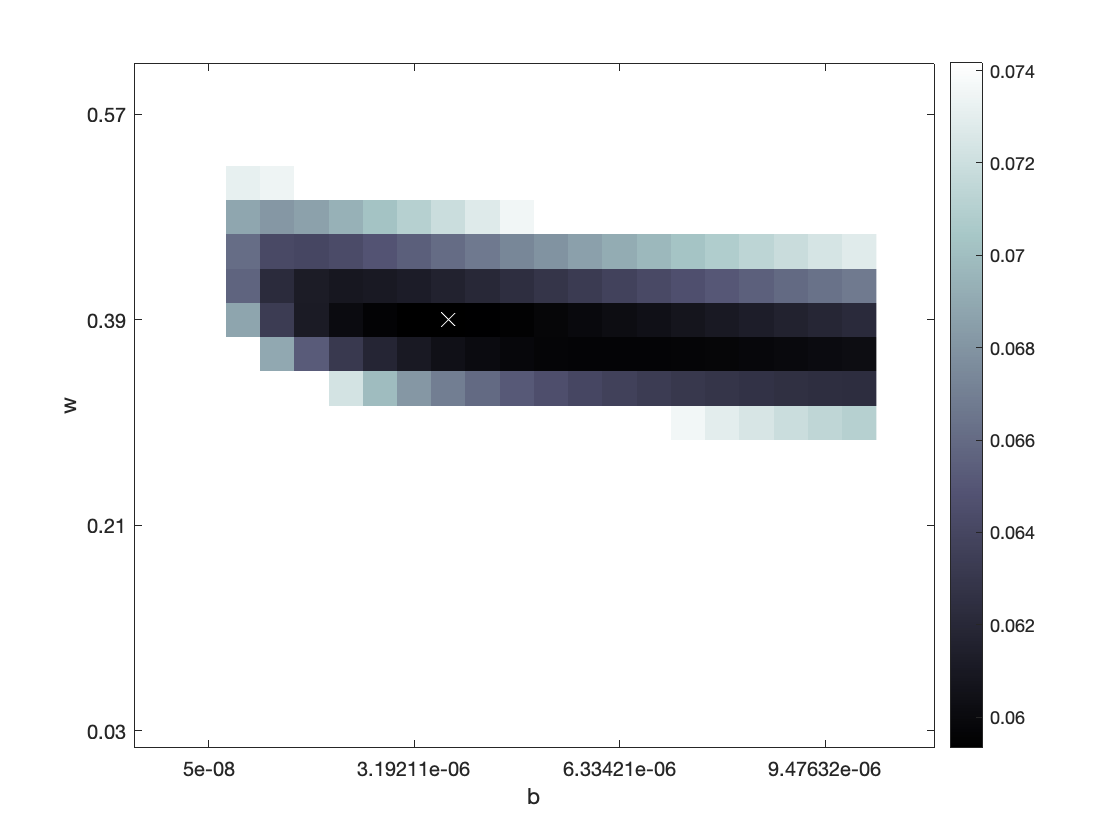

n_select = .95;
OldOTS('remove_redundacy_linspace', ds, roi, n_select); 

The impact of the exponent is more salient when we put $b$ into a log space. 

The lowest (grid) loss:


loss_min_global = 0.0593

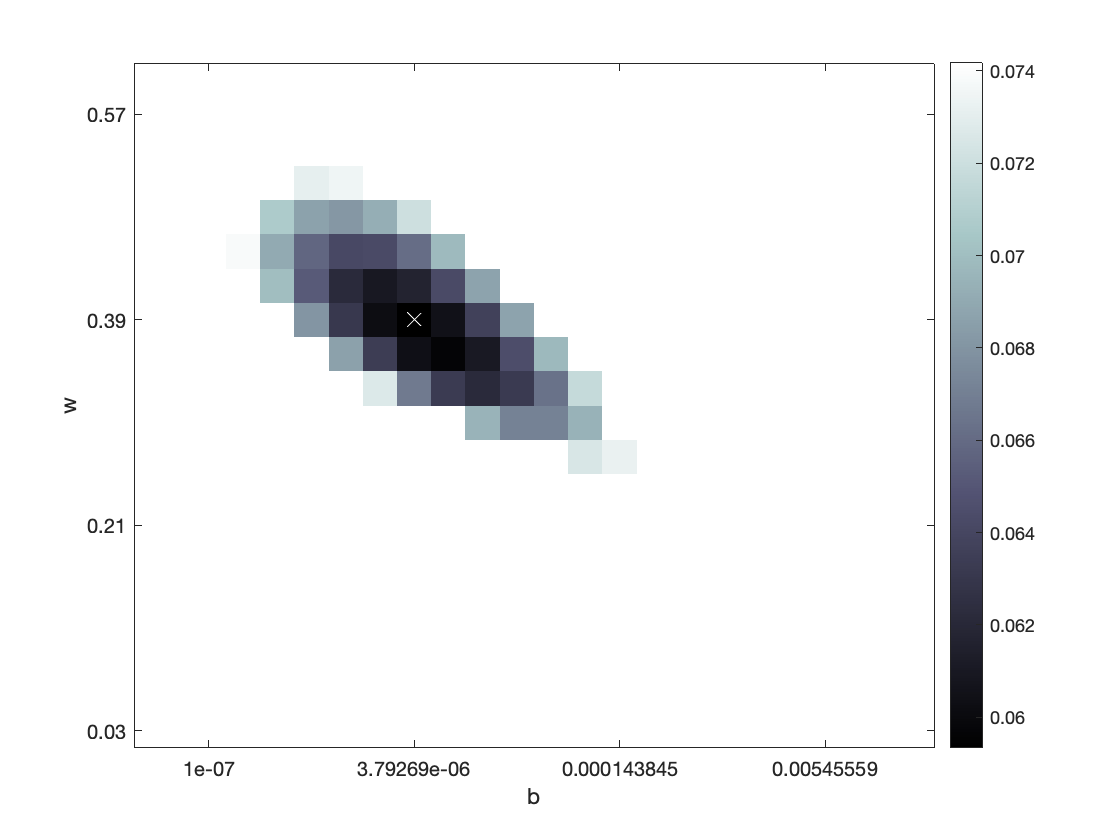

n_select = .95;
OldOTS('remove_redundacy_logspace', ds, roi, n_select); 

The correlation between $w$ and $b$ is stronger when we reduce the exponent to make the function more sub-linear.  

The lowest (grid) loss:


loss_min_global = 0.0681

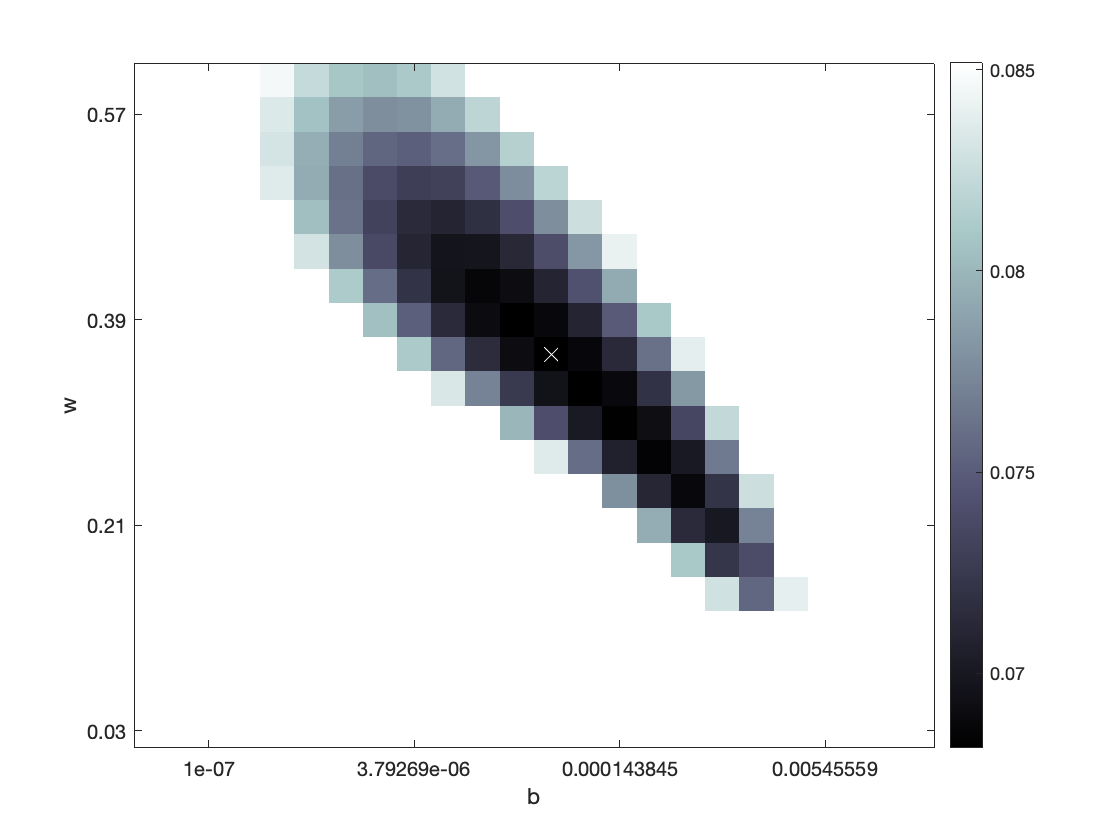

ans = logical
   1


n_select = .7;
OldOTS('remove_redundacy_logspace', ds, roi, n_select);

The lowest (grid) loss:


loss_min_global = 0.0592

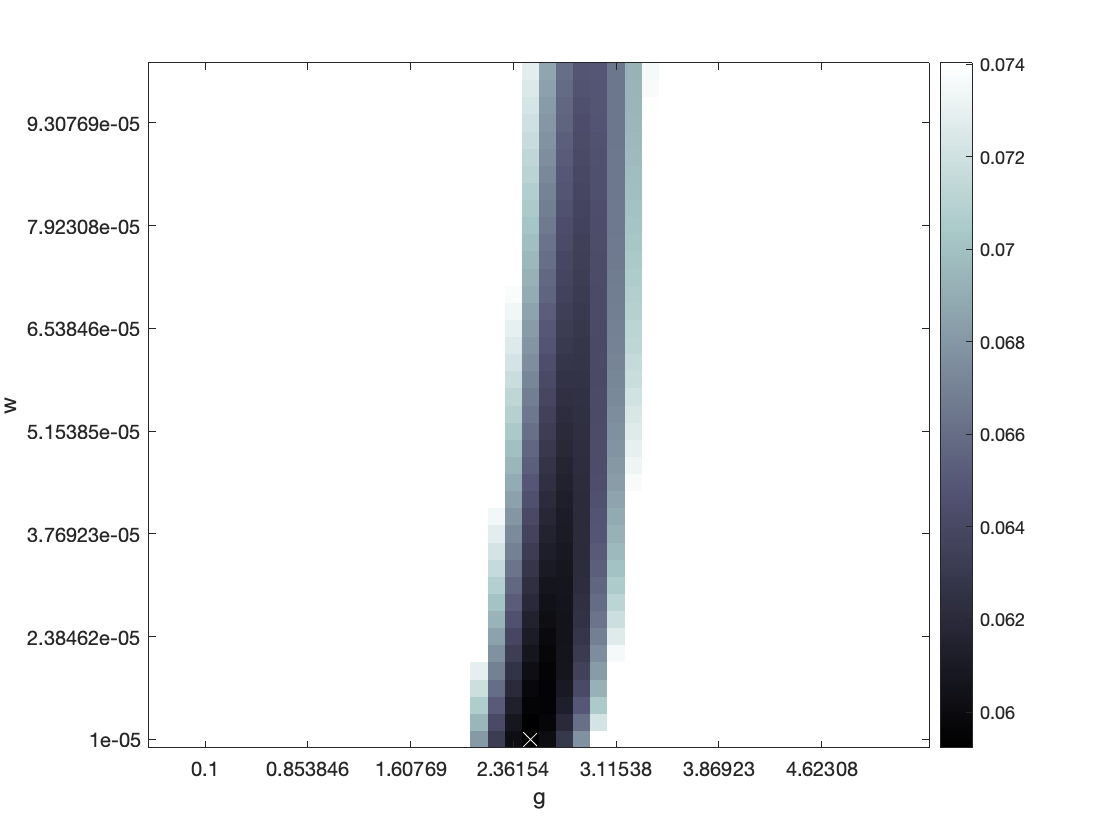

n_select = .95; ds =1; roi=2;
OldOTS('OTS_classic_lossLand', ds, roi, n_select); 

The lowest (grid) loss:


loss_min_global = 0.0664

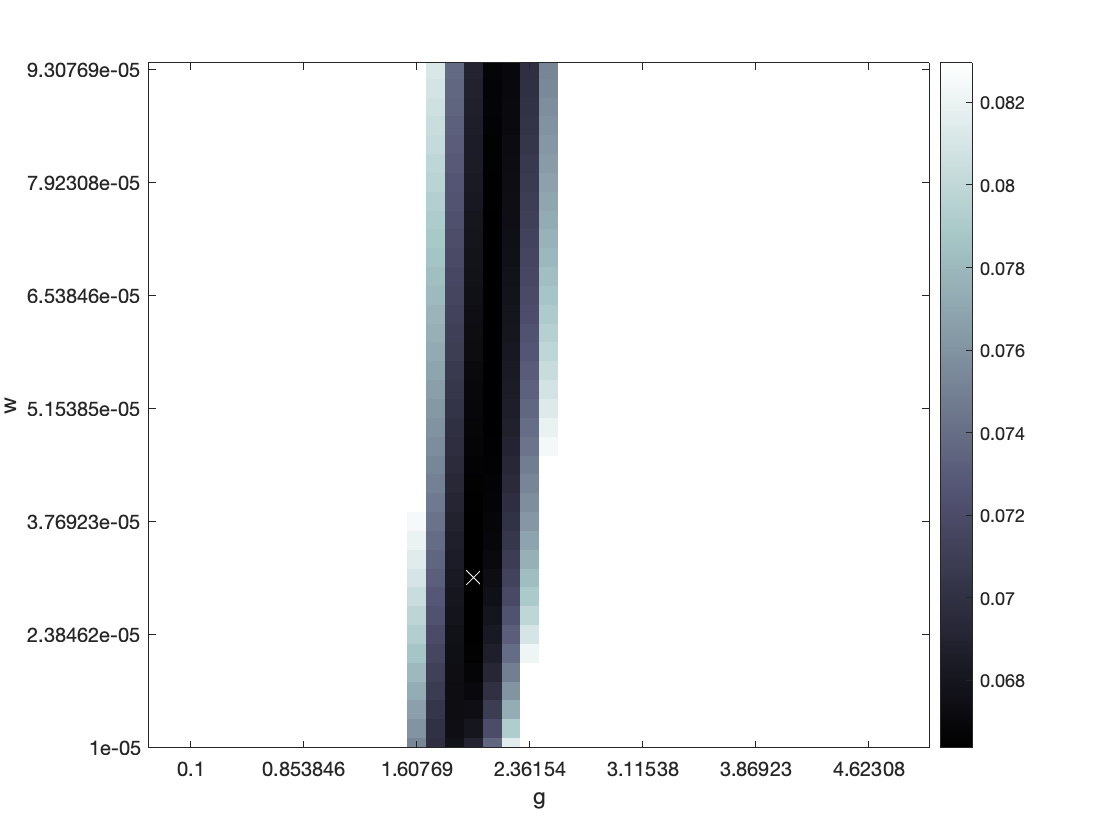

n_select = .75; ds =1; roi=2;
OldOTS('OTS_classic_lossLand', ds, roi, n_select); 

figure();
v = linspace(1, 10, 20); 
n = 0.9;
g = (10./v).^n;
max(g).^(1/n), min(g).^(1/n)

ans = 10.0000

ans = 1

maxw = max(g).^(1/n) * 1e-6

maxw = 1.0000e-05

minw = min(g).^(1/n) * 1e-6

minw = 1.0000e-06

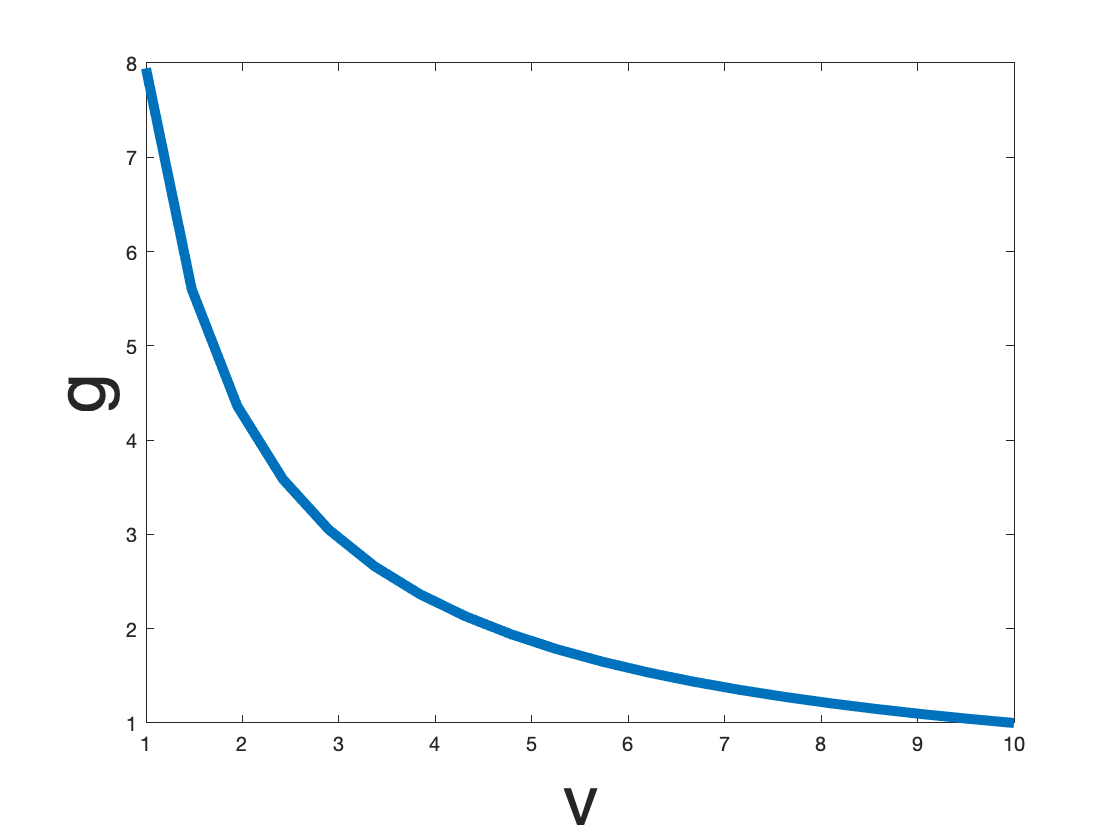


plot(v, g, 'LineWidth', 5)
xlabel('v', "FontSize", 35)
ylabel('g', "FontSize", 35)

figure();
u = linspace(1, 10, 20); 
n = 0.9;
g = (10^6./u).^n;
max(g).^(1/n), min(g).^(1/n)

ans = 1.0000e+06

ans = 1.0000e+05

maxw = max(g).^(1/n) * 1e-1

maxw = 1.0000e+05

minw = min(g).^(1/n) * 1e-1

minw = 1.0000e+04

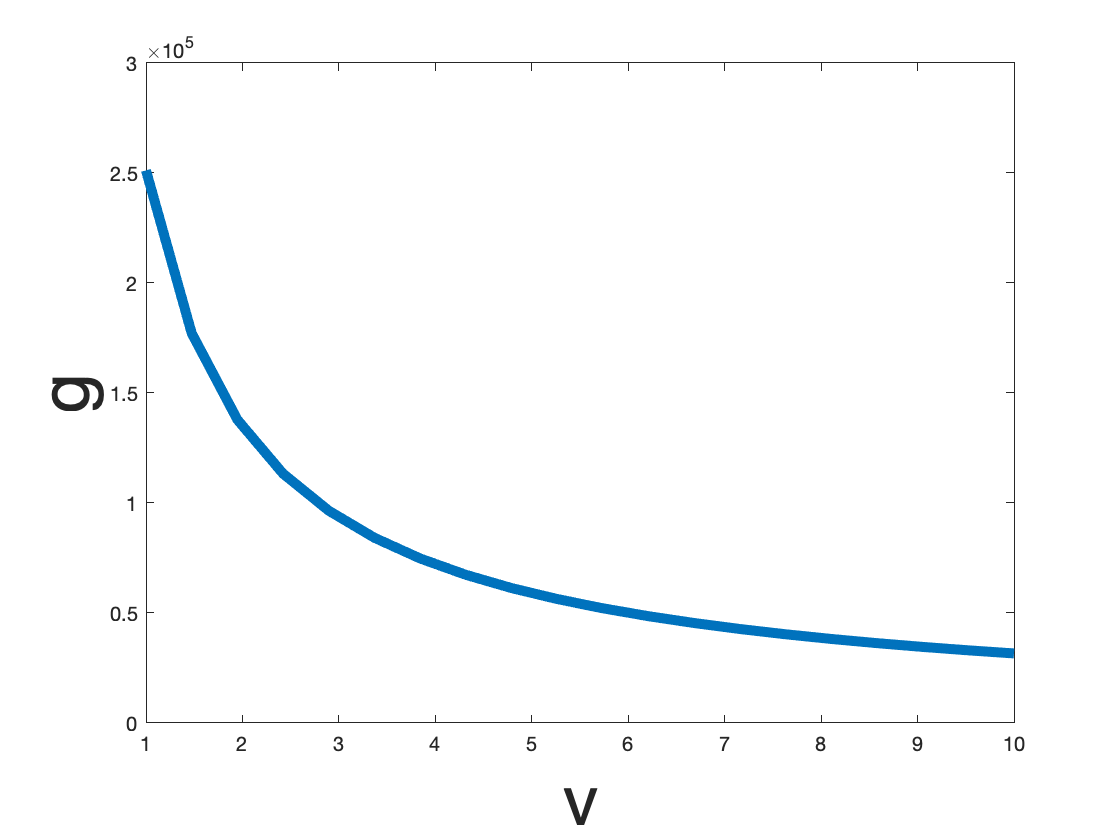

plot(v, g, 'LineWidth', 5)
xlabel('v', "FontSize", 35)
ylabel('g', "FontSize", 35)